# Test Signals

addpath(genpath('Test Signals'));
[diracMono, fs] = audioread('diracTest.wav');
[dirac] = [diracMono, diracMono];

[essMono, fs] = audioread('sineSweep.wav');
[ess] = [essMono, essMono];

[pinkNoiseMono, fs] = audioread('pinkNoise.wav');
[pink_noise] = [pinkNoiseMono, pinkNoiseMono];

[guitar, fs] = audioread('Guitar.wav');

% Set buffer parameters
buff_length = 480;

% Initialize plugin
chorus = DelayLah();  

% Set parameters
chorus.delayTime = 0.025;
chorus.feedback = 0.8;
chorus.modulationRate = 0.8;
chorus.modulationDepth = 0.025;
chorus.dryWetMix = 0.7;


## Dirac

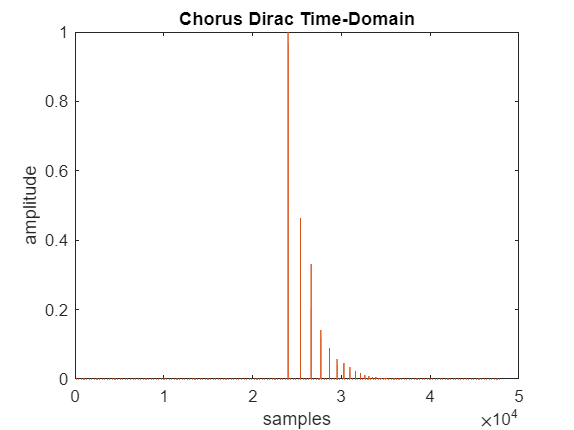

chorus.reset();
dirac_out = chorus.process(dirac);

figure(1);
plot(dirac_out);
title('Chorus Dirac Time-Domain');
xlabel('samples');
ylabel('amplitude');

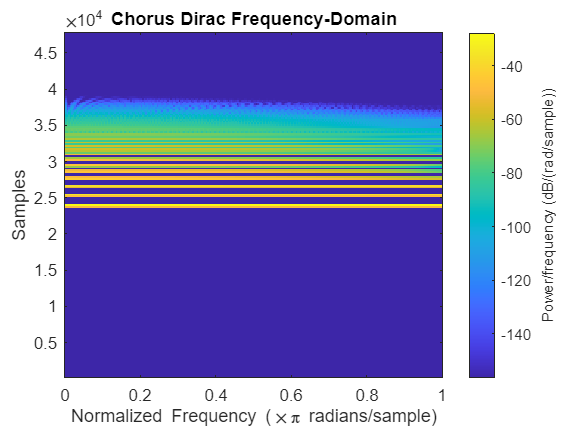



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(dirac_out(:,1), hamming(win_length), overlap_length, nfft);
title('Chorus Dirac Frequency-Domain');

## ESS

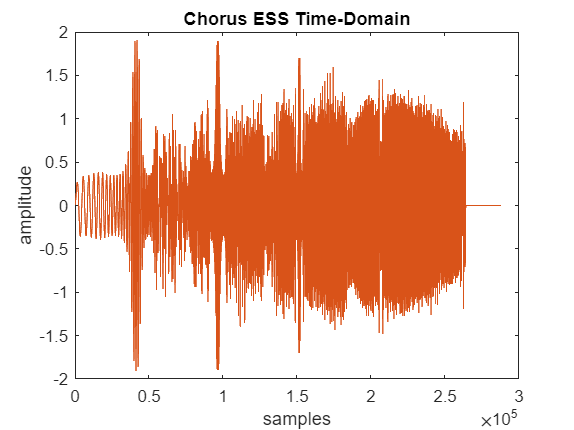


chorus.reset();
ess_out = chorus.process(ess);

figure(3);
plot(ess_out);
title('Chorus ESS Time-Domain');
xlabel('samples');
ylabel('amplitude');

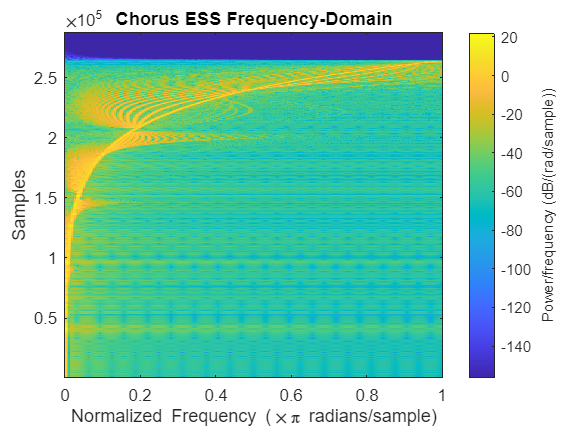



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(4);
spectrogram(ess_out(:,1), hamming(win_length), overlap_length, nfft);
title('Chorus ESS Frequency-Domain');

## Pink Noise

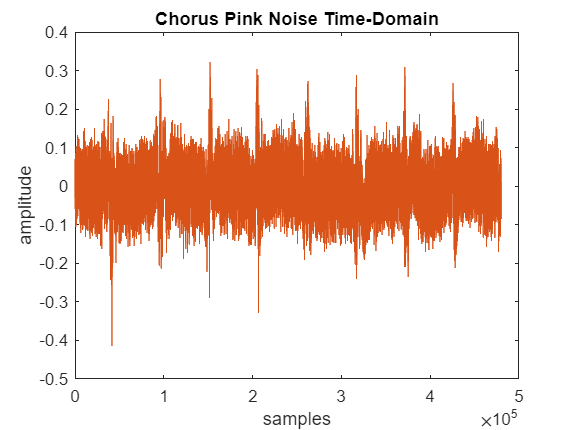


chorus.reset();
pink_noise_out = chorus.process(pink_noise);

figure(5);
plot(pink_noise_out);
title('Chorus Pink Noise Time-Domain');
xlabel('samples');
ylabel('amplitude');

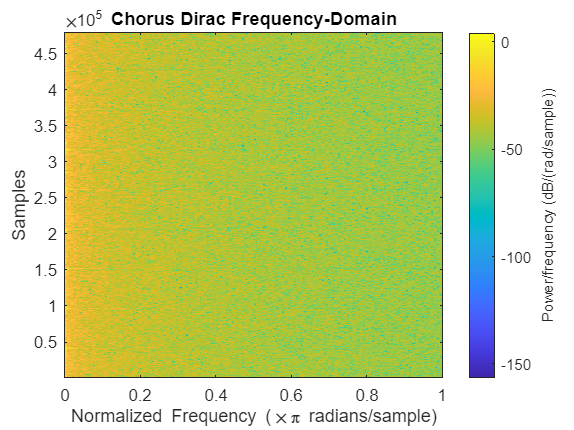



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(pink_noise_out(:,1), hamming(win_length), overlap_length, nfft);
title('Chorus Dirac Frequency-Domain');

## Guitar

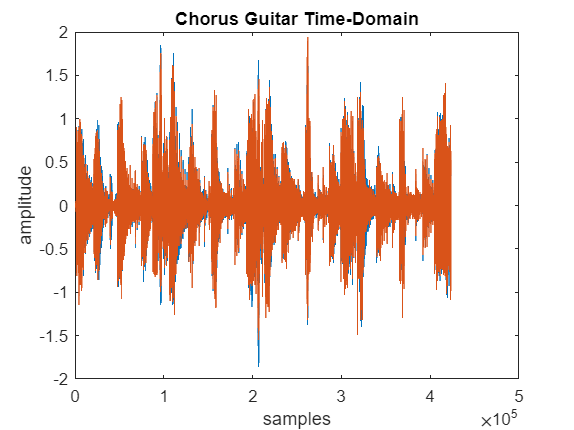

chorus.reset();
guitar_out = chorus.process(guitar);

figure(1);
plot(guitar_out);
title('Chorus Guitar Time-Domain');
xlabel('samples');
ylabel('amplitude');

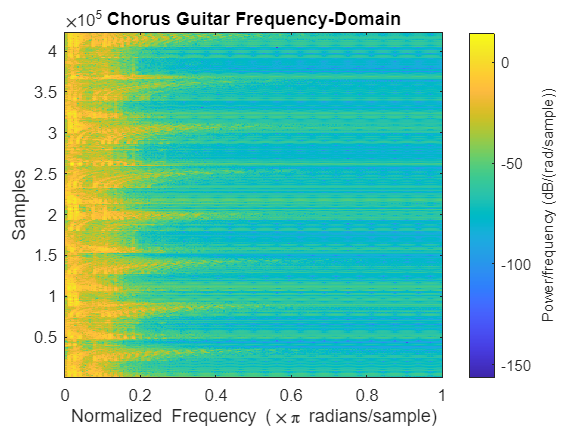



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(guitar_out(:,1), hamming(win_length), overlap_length, nfft);
title('Chorus Guitar Frequency-Domain');